# Egocentric Bearing

% load 'sample.mat'
filepath = 'D:\Data\Dataset\sample.mat'; % add your own filepath
load(filepath);

% grab position variables
x = position(:,2);  % x-coord of LED1
y = position(:,3);  % y-coord of LED1
x2 = position(:,4); % x-coord of LED2
y2 = position(:,5); % y-coord of LED2

% define reference point
xGoal = 89;
yGoal = 83;

% plot the behavior to make sure it looks like what we expect
disp("Does the behavior look as we expect?")

Does the behavior look as we expect?


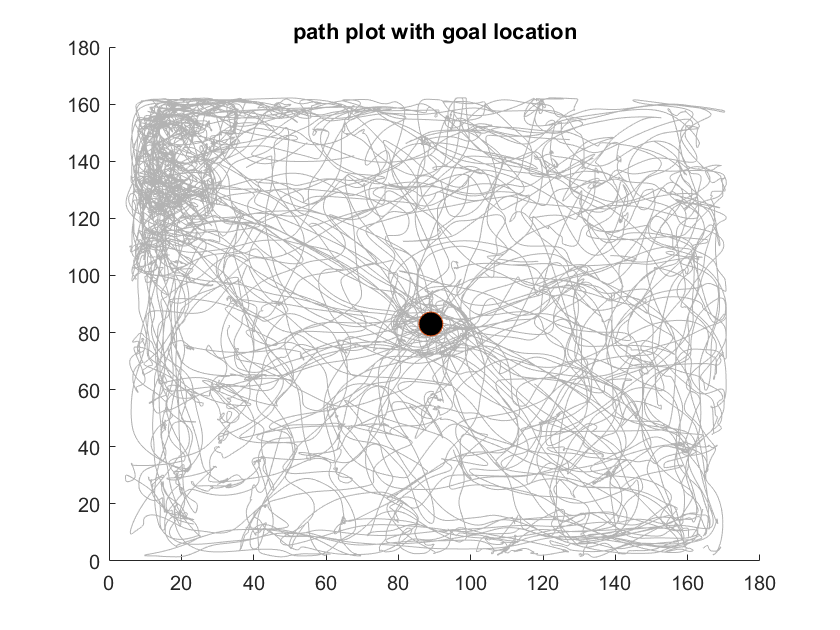

figure
title("path plot with goal location")
hold on;
plot(x, y, 'Color', [.7 .7 .7]); % path
goal_plot = plot(xGoal, yGoal, 'o', 'MarkerSize', 12); % goal location
set(goal_plot, 'markerfacecolor', 'k');
hold off;


% Calculate head-direction values. I do this using the 'atan2d' function
% which is the same that we will use to calculate the allocentric bearing
% (theta). This is the same function that you were using before (atan2) with the
% exception that it gives its output in *degrees* instead of *radians*.

% the function you used before
disp("The function you used before:")

The function you used before:


help atan2

 atan2  Four quadrant inverse tangent.
    atan2(Y,X) is the four quadrant arctangent of the elements of X and Y
    such that -pi <= atan2(Y,X) <= pi. X and Y must have compatible sizes.
    In the simplest cases, they can be the same size or one can be a
    scalar. Two inputs have compatible sizes if, for every dimension, the
    dimension sizes of the inputs are either the same or one of them is 1.
 
    See also atan, atan2d.

    Reference page for atan2
    Other functions named atan2




% the function we want to use now
disp("The function we want to use now:")

The function we want to use now:


help atan2d

 atan2d  Four quadrant inverse tangent, result in degrees.
    atan2d(Y,X) is the four quadrant arctangent of the elements of X and Y
    such that -180 <= atan2d(Y,X) <= 180. X and Y must have compatible
    sizes. In the simplest cases, they can be the same size or one can be a
    scalar. Two inputs have compatible sizes if, for every dimension, the
    dimension sizes of the inputs are either the same or one of them is 1.
 
    See also atand, atan2.

    Reference page for atan2d
    Other functions named atan2d



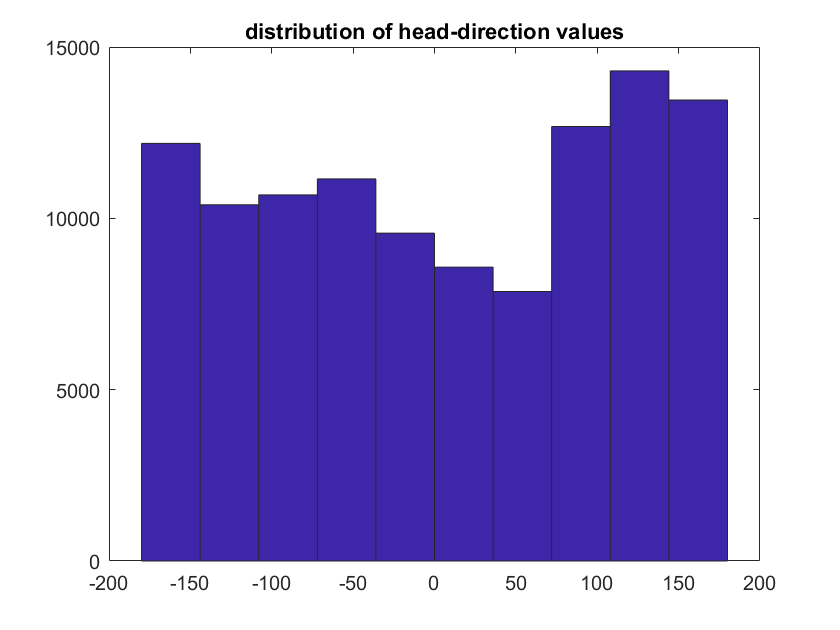


% Now make the head_direction calculation
head_direction = atan2d(y2-y, x2-x);

% check that the obtained values for head-direction fall into the interval
% [-180, 180]. * If they don't fall into this interval, this will cause a
% huge problem!
figure
hist(head_direction)
title("distribution of head-direction values")

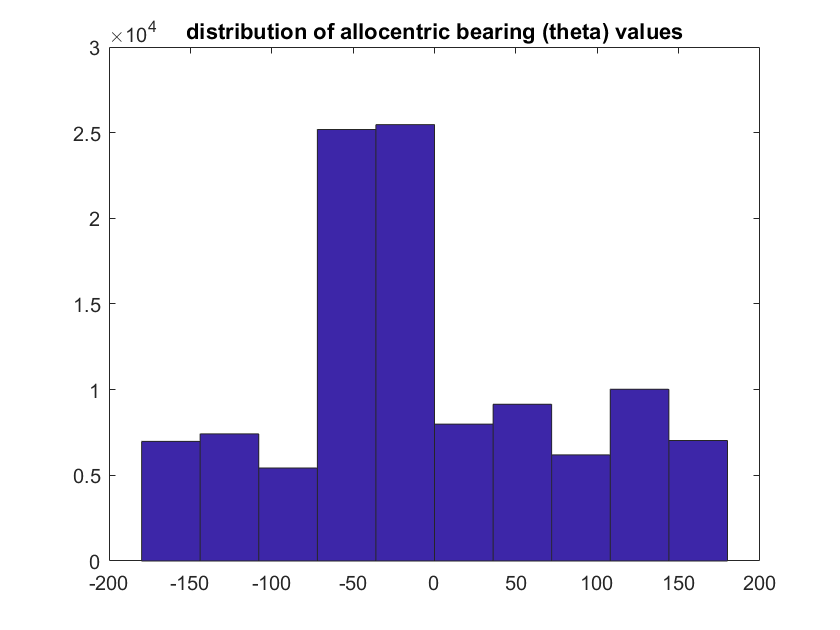


% define delta(x) and delta(y)
a = xGoal - x; 
b = yGoal - y;

% use the 'atan2d' function to calculate 'theta' (which is the allocentric
% bearing)
theta = atan2d(b, a);

% plot a histogram of these values to see what we get
figure
hist(theta)
title("distribution of allocentric bearing (theta) values")


% Like head direction, these values also lie within the range of -180 to
% + 180. But the next step is where it becomes tricky. Let's first take a
% look at what you had in the original code. I'll break it down into
% multiple lines to show what the distribution (outputs) look like at each
% step.


## I. Calculation of egocentric bearing, as it is dMan

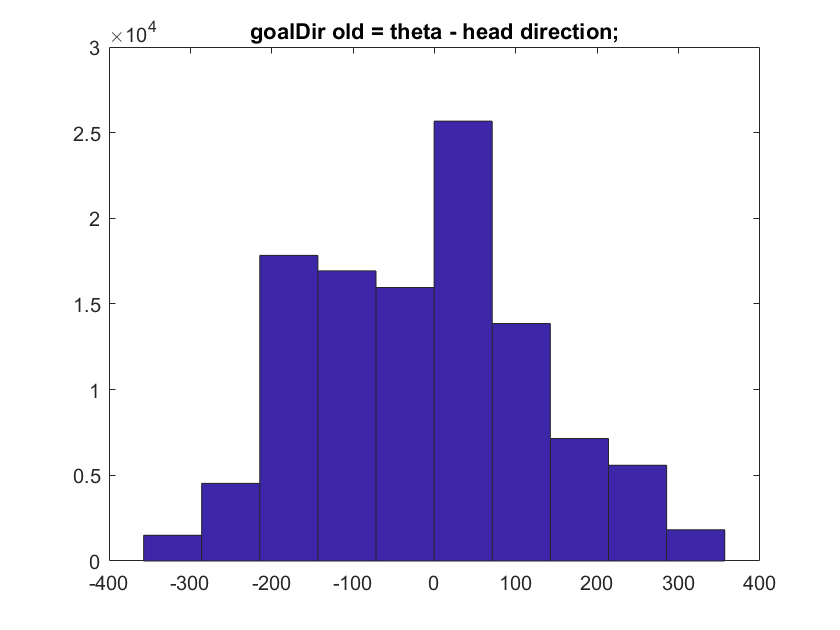

% so first you subtract the head_direction values from the allocentric
% bearing (theta) which is correct.
goalDir_old = theta - head_direction; 

% here is the distribution that we get 
figure
hist(goalDir_old)
title("goalDir old = theta - head direction;")


% we can see here that we get values that lie outside of the range we are
% interested in, which is -180 to +180. We see that instead, we get a
% maximum value of ~360 degrees and a minimum value of ~ -360 degrees.
max_value_here = nanmax(goalDir_old)

max_value_here = 356.6406

min_value_here = nanmin(goalDir_old)

min_value_here = -357.5242


% It is okay that we now have numbers within the range [-360 +360] but what
% we need to do is apply a 'circular subtraction', which we can do by
% identifying values that are negative and "wrapping" them back around the
% circle by adding 360 degrees. By taking the absolute value, you are
% not allowing the numbers to wrap around the circle as they need to since
% these numbers we're working with (egocentric bearing, head direction, etc.)
% are all circular variables.

% but just to show you what happens, here's what we get when we take the
% absolute value of the numbers
disp("Here's the distribution of values we get for goal direction when we use the formula Goal Direction = abs(theta - head_direction)")

Here's the distribution of values we get for goal direction when we use the formula Goal Direction = abs(theta - head_direction)


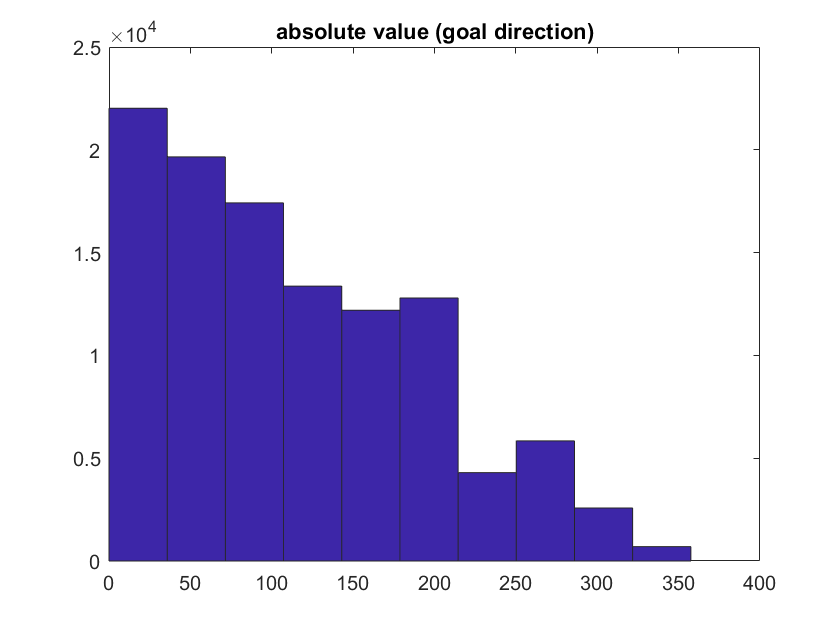

figure
goalDir_old_abs = abs(goalDir_old);
hist(goalDir_old_abs)
title("absolute value (goal direction)")

## II. Calculation of egocentric bearing with corrections

% Now lets perform a circular subtraction instead of taking the absolute
% value:

% it starts off the same...
goalDir_new = theta - head_direction;

% now we 'wrap' negative numbers around the circle
neg_idx = find(goalDir_new<0);
goalDir_new(neg_idx) = goalDir_new(neg_idx)+360;

disp("Here are the results of the circular subtraction:")

Here are the results of the circular subtraction:


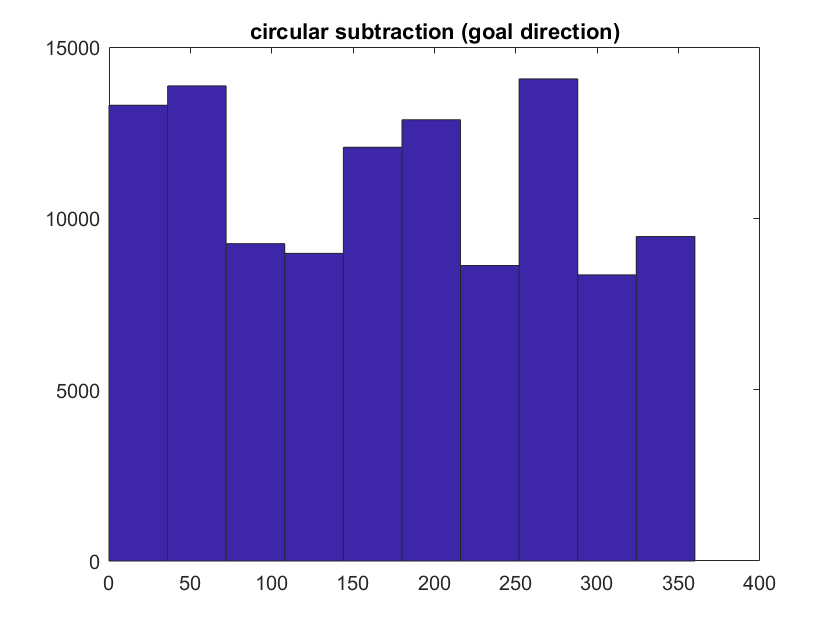

hist(goalDir_new)
title("circular subtraction (goal direction)")


% now we can shift them back into the [-180 180 interval] if we don't want
% to see the numbers from 0 to 360 degrees.
goalDir_new_shifted = goalDir_new - 180;

disp("Here are the results of the circular subtraction after shifting values back to -180 to +180 degrees:")

Here are the results of the circular subtraction after shifting values back to -180 to +180 degrees:


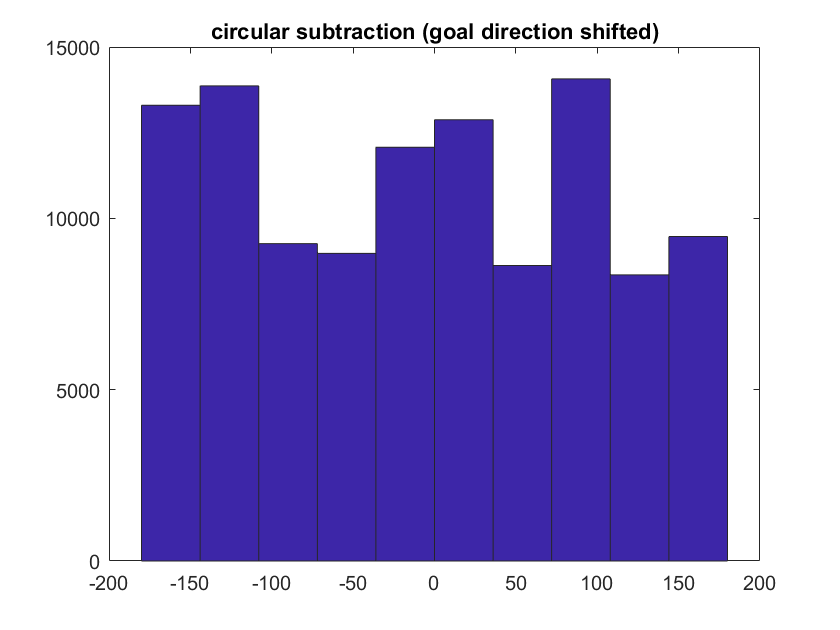

hist(goalDir_new_shifted)
title("circular subtraction (goal direction shifted)")

## III. Here's what the code should look like:

% Here's the short version of everything above:

% grab position variables
x = position(:,2);  % x-coord of LED1
y = position(:,3);  % y-coord of LED1
x2 = position(:,4); % x-coord of LED2
y2 = position(:,5); % y-coord of LED2

% define reference point
xGoal = 89;
yGoal = 83;

% calculate head direction
head_direction = atan2d(y2-y, x2-x);

% calculate theta
a = xGoal - x; b = yGoal - y; % deltas
theta = atan2d(b, a);

% calculate goal direction
goalDir = theta - head_direction;

% wrap values around the circle
neg_idx = find(goalDir<0);
goalDir(neg_idx) = goalDir(neg_idx)+360;

% shift back to [-180 180]
goalDir = goalDir - 180;